# RVC2: Chapter 13 - Image Feature Extraction

format compact
close all
clear

Movie destructor, delete movie object


clc

## 13.1 Region Features

## 13.1.1 Classification

## 13.1.1.1  Grey-level classification

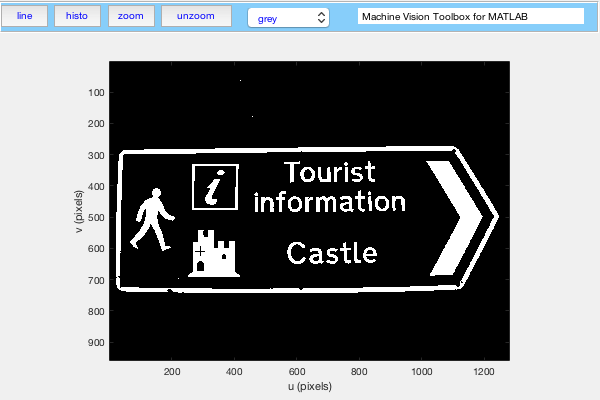

castle = iread('castle.png', 'double');

idisp(castle > 0.7)

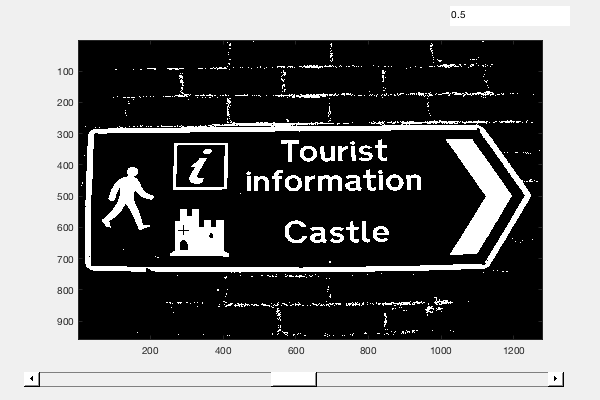


ithresh(castle)

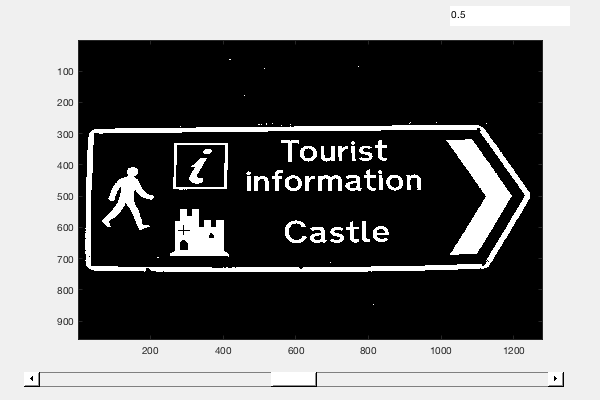


ithresh(castle*0.8)

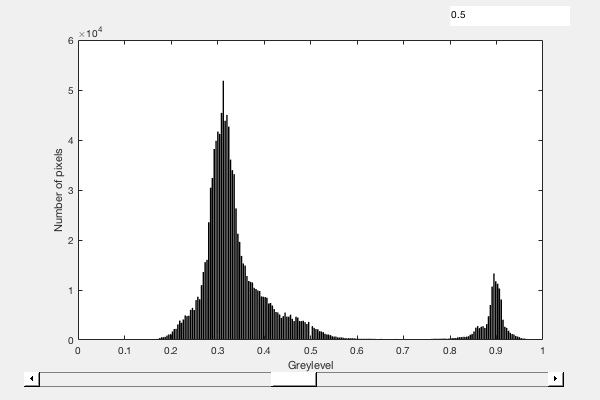


ihist(castle);


t = otsu(castle)

t = 0.5898


castle = iread('castle2.png', 'double');

t = otsu(castle)

t = 0.5859

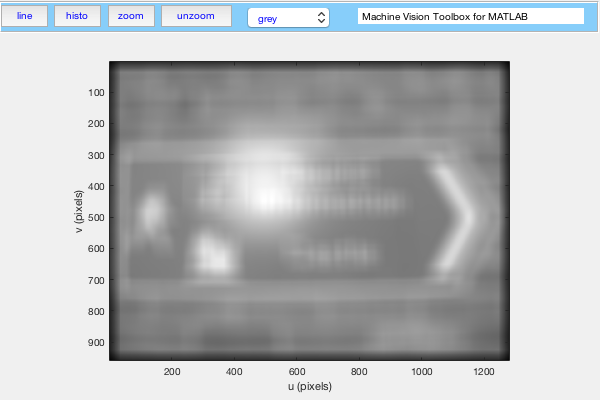


t = niblack(castle, -0.2, 35);
idisp(t)

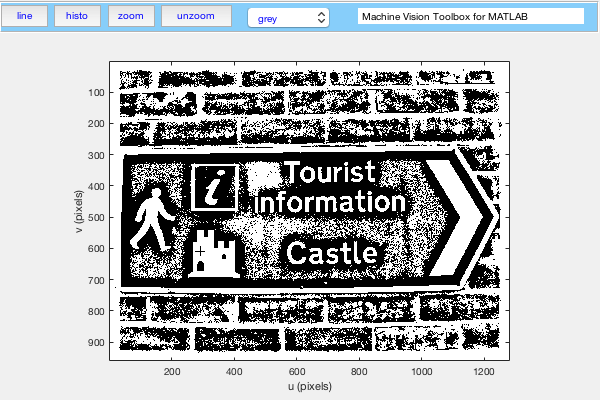


idisp(castle >= t)



[mser,nsets] = imser(castle, 'area', [100 20000]);

95 MSERs found


nsets

nsets = 95


nsets

nsets = 95

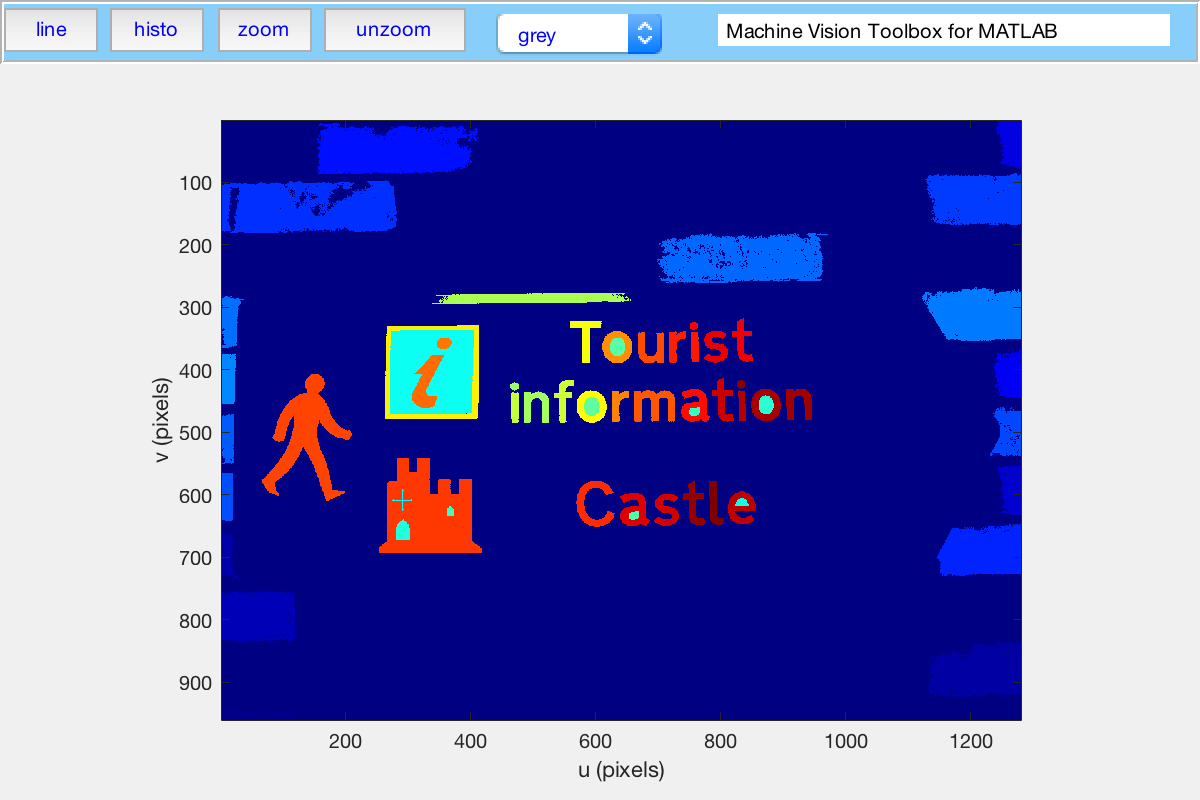


idisp(mser, 'colormap', 'jet')

## 13.1.1.2  Color classification

im_targets = iread('yellowtargets.png');

im_garden = iread('tomato_124.jpg');

randinit
[cls, cab,resid] = colorkmeans(im_targets, 2, 'ab');

 1:      -0.819      0.4783 
 2:       57.61      -4.191 



cab

cab =    -0.8190    0.4783
   57.6140   -4.1910

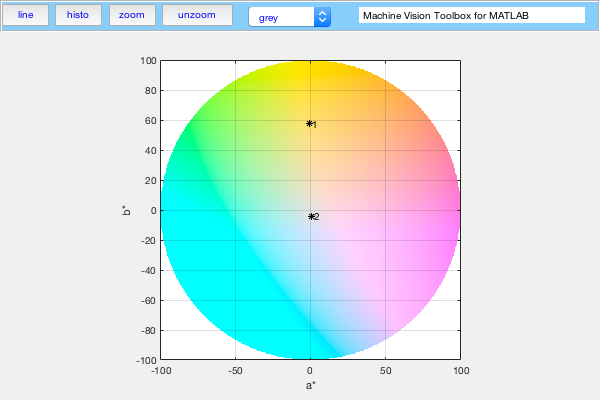


showcolorspace(cab, 'ab');


colorname(cab(:,1)', 'ab')

loading rgb.txt


ans = gold4


resid

resid = 2.8897e+03

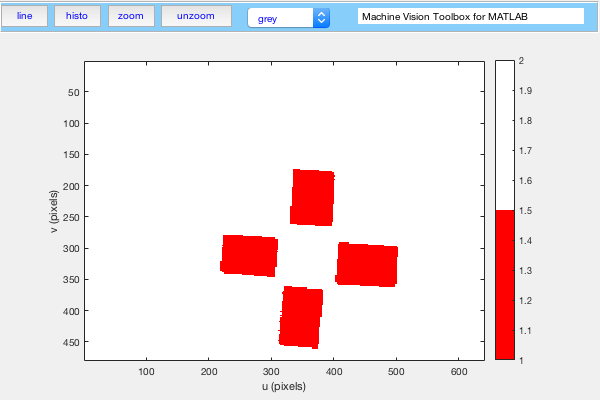


idisp(cls, 'colormap', flag(2), 'bar')


cls = colorkmeans(im_targets, cab, 'ab');

 1:      -0.819      0.4783 
 2:       57.61      -4.191 


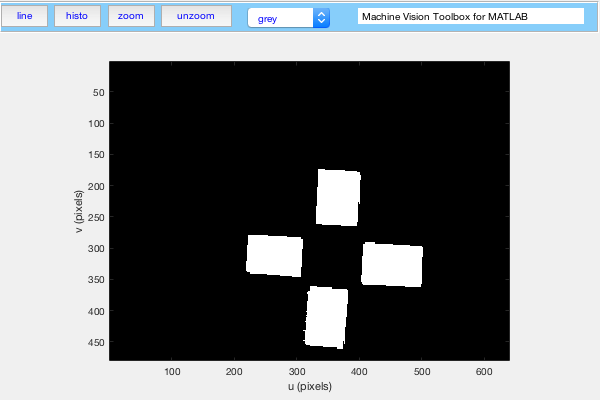


cls1 = (cls == 1);

idisp(cls1)


targets_binary = iopen(cls1, kcircle(2));


randinit
[cls, cab] = colorkmeans(im_garden, 3, 'Lab');

 1:      -16.33       44.06      -1.507 
 2:       28.88       26.79       3.387 


cab

cab =   -16.3326   44.0622   -1.5073
   28.8824   26.7948    3.3873


colorname(cab(:,2)', 'ab')

ans = brown4

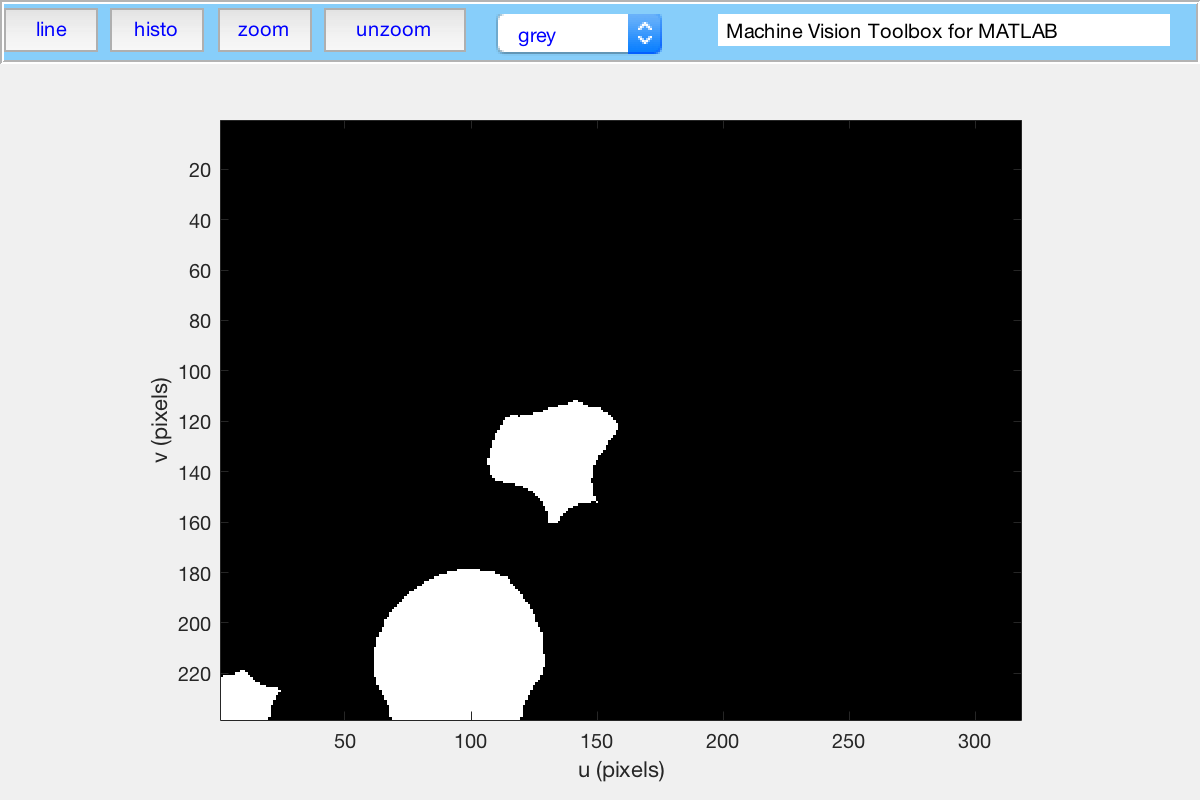


cls2 = (cls == 2);

tomatoes_binary = iclose(cls2, kcircle(15));

idisp(tomatoes_binary) %DIFF

## 13.1.2  Representation

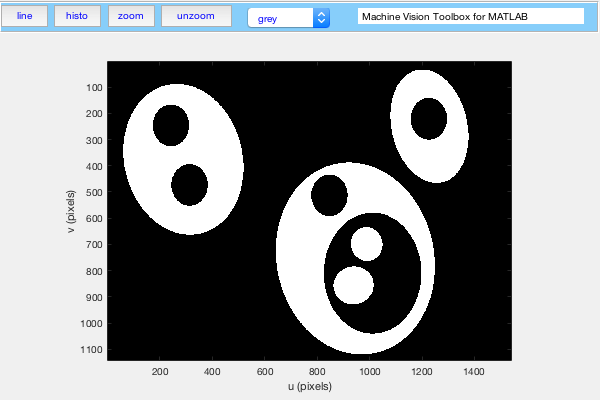

im = iread('multiblobs.png');

idisp(im)


[label, m] = ilabel(im);

m

m = 11

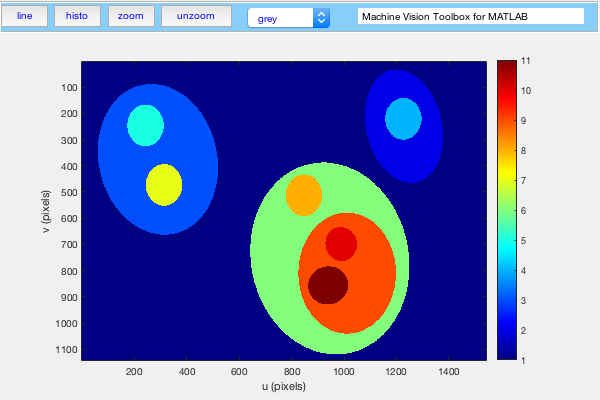


idisp(label, 'colormap', jet, 'bar')

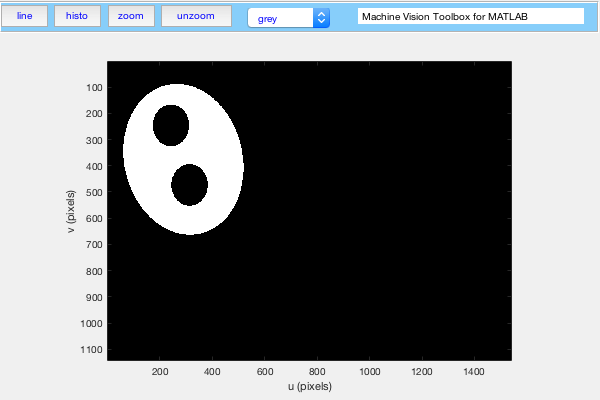


reg3 = (label==3);
idisp(reg3)


sum(reg3(:))

ans = 171060


[label, m, parents, cls] = ilabel(im);

parents'

ans =    0   1   1   2   3   1   3   6   6   9   9


cls'

ans =      0     1     1     0     0     1     0     0     0     1     1

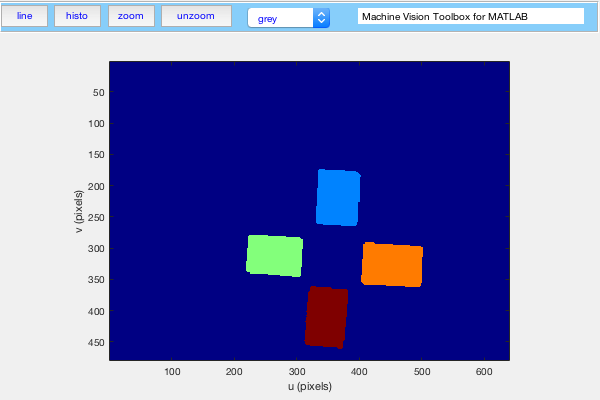


targets_label = ilabel(targets_binary);
idisp(targets_label, 'colormap', 'jet');

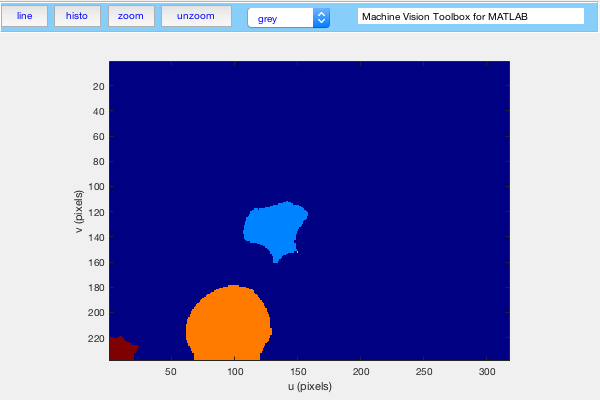


tomatoes_label = ilabel(tomatoes_binary);
idisp(tomatoes_label, 'colormap', 'jet');

## 13.1.2.1  Graph-based segmentation

im = iread('58060.jpg');

[label, m] = igraphseg(im, 1500, 100, 0.5);
m

m = 28

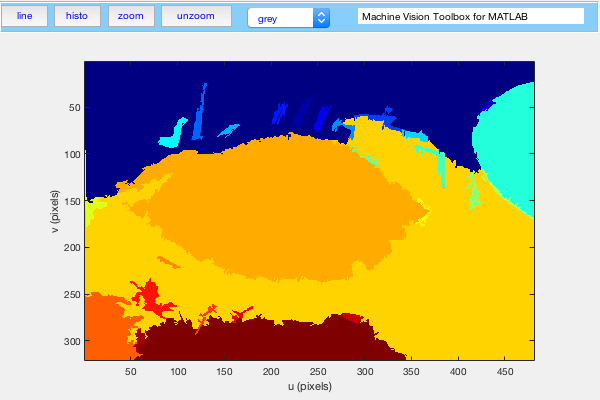

idisp(label, 'colormap', 'jet')

## 13.1.3 Description

## 13.1.3.1  Bounding boxes

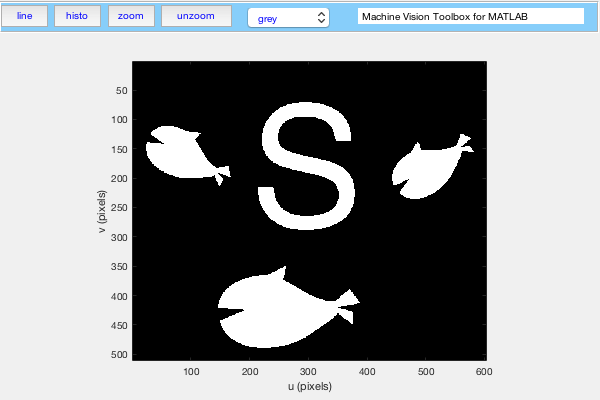

sharks = iread('sharks.png');
idisp(sharks)  % DIFF

[label, m] = ilabel(sharks);


blob = (label == 2);
idisp(blob)  % DIFF

sum(blob(:))

ans = 7728


[v,u] = find(blob);

about(u)

u [double] : 7728x1 (61.8 kB)



umin = min(u)

umin = 443

umax = max(u)

umax = 581

vmin = min(v)

vmin = 125

vmax = max(v)

vmax = 235

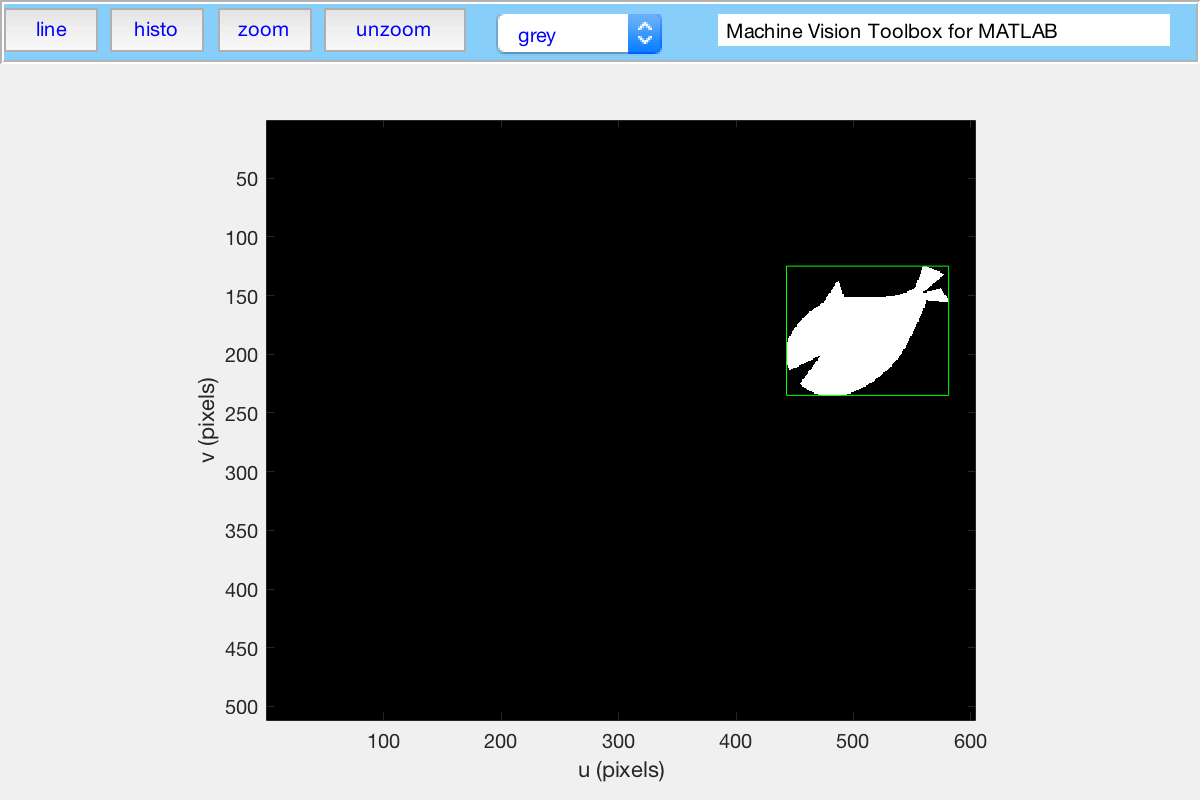


plot_box(umin, vmin, umax, vmax, 'g')

## 13.1.3.2  Moments

m00 = mpq(blob, 0, 0)

m00 = 7728


uc = mpq(blob, 1, 0) / m00

uc = 503.4981

vc = mpq(blob, 0, 1) / m00

vc = 184.7285


hold on; %DIFF
plot(uc, vc, 'gx', uc, vc, 'go');

u20 = upq(blob, 2, 0); u02 = upq(blob, 0, 2); u11 = upq(blob, 1, 1);
J = [ u20 u11; u11 u02]

J =    1.0e+06 *
    7.8299   -2.9169
   -2.9169    4.7328

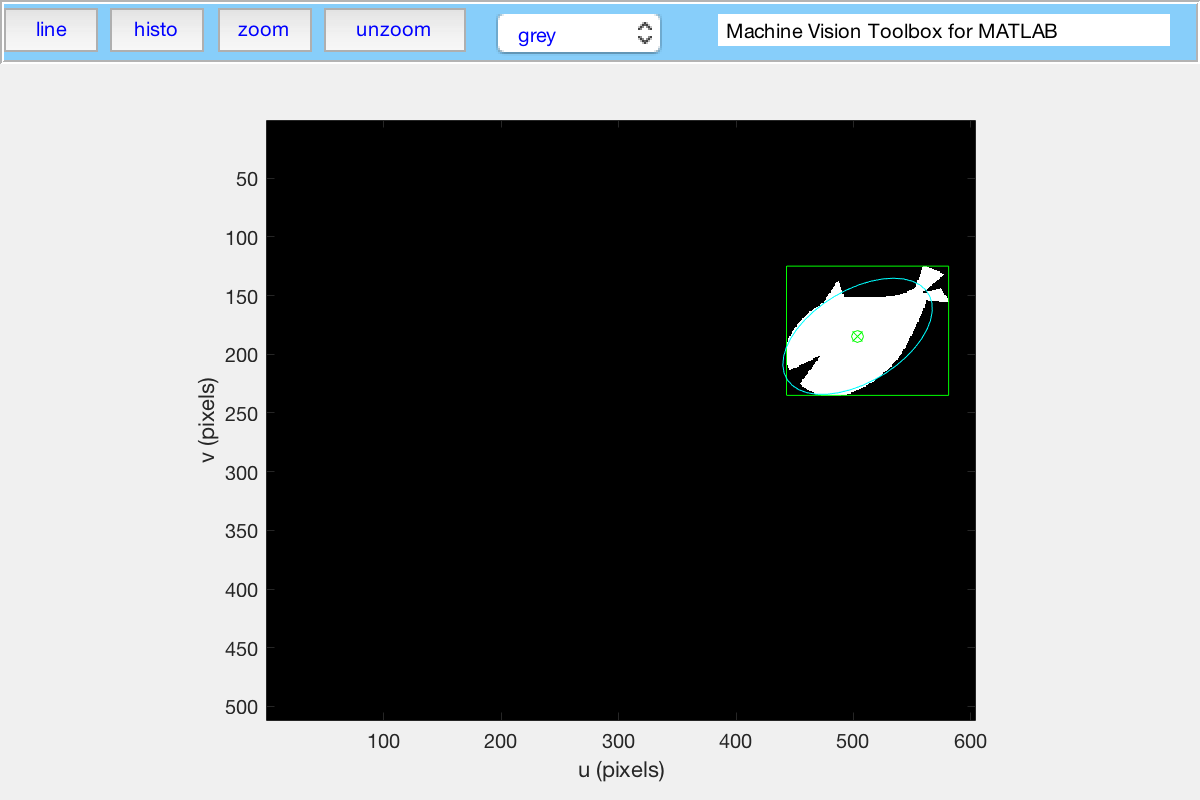



plot_ellipse(4*J/m00, [uc, vc], 'c');


lambda = eig(J)

lambda =    1.0e+06 *
    2.9788
    9.5838


a = 2 * sqrt(lambda(2) / m00)

a = 70.4313

b = 2 * sqrt(lambda(1) / m00)

b = 39.2663


b/a

ans = 0.5575


[x,lambda] = eig(J);
x

x =    -0.5153   -0.8570
   -0.8570    0.5153


v = x(:,end);

atand( v(2)/v(1) )

ans = -31.0185

## 13.1.3.3  Blob features

f = imoments(blob)

f = 
area=7728, cent=(503.5,184.7), theta=-0.54, b/a=0.558


f.uc

ans = 503.4981

f.theta

ans = -0.5414

f.aspect

ans = 0.5575


f.moments.m00

ans = 7728

f.moments.u11

ans = -2.9169e+06


%
fv = iblobs(sharks)

fv = 
(1) area=14899, cent=(298.0,181.0), theta=1.48, b/a=0.702, color=1, label=1, touch=0, parent=4 
(2) area=7728, cent=(503.5,184.7), theta=-0.54, b/a=0.558, color=1, label=2, touch=0, parent=4 
(3) area=7746, cent=(84.2,160.7), theta=0.50, b/a=0.558, color=1, label=3, touch=0, parent=4   
(4) area=258946, cent=(306.7,252.9), theta=0.05, b/a=0.831, color=0, label=4, touch=1, parent=0
(5) area=18814, cent=(246.8,426.9), theta=-0.02, b/a=0.559, color=1, label=5, touch=0, parent=4



fv(3).class

ans = 1

fv(3).parent

ans = 4

fv(3).touch

ans =    0

fv(3).umin

ans = 24

fv(3).aspect

ans = 0.5580

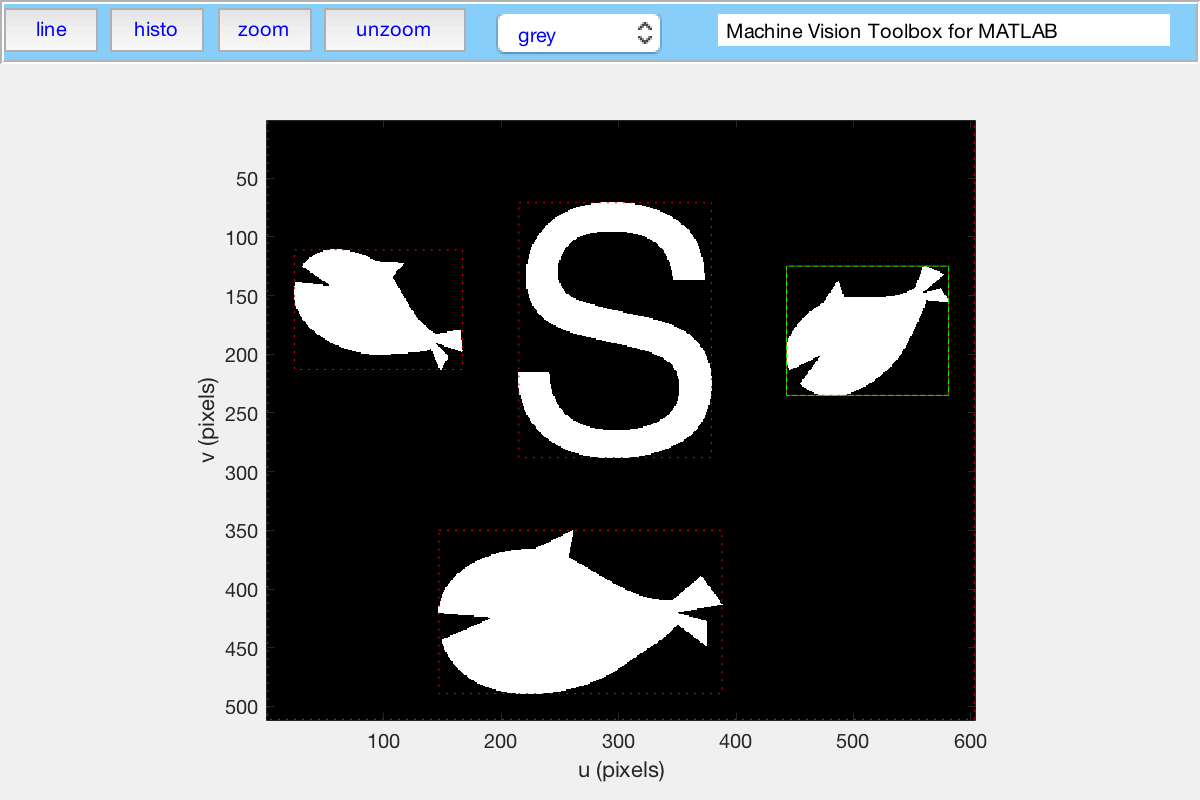

idisp(sharks)
fv(2).plot_box('g')

fv.plot_box('r:')


fv(4).children

ans =      1     2     3     5


fv = iblobs(tomatoes_binary, 'area', [1000, 5000])

fv = 
(1) area=1529, cent=(132.6,132.9), theta=-0.36, b/a=0.866, color=1, label=2, touch=0, parent=1
(2) area=3319, cent=(95.5,210.9), theta=-0.33, b/a=0.886, color=1, label=4, touch=1, parent=0 



fv = iblobs(tomatoes_binary, 'touch', 0)

fv = 
(1) area=1529, cent=(132.6,132.9), theta=-0.36, b/a=0.866, color=1, label=2, touch=0, parent=1



fv = iblobs(tomatoes_binary, 'area', [1000 5000], 'touch', 0, 'class', 1)

fv = 
(1) area=1529, cent=(132.6,132.9), theta=-0.36, b/a=0.866, color=1, label=2, touch=0, parent=1


## 13.1.3.4  Shape from moments

sharks = iread('sharks.png');

[fv,L] = iblobs(sharks, 'class', 1);
fv

fv = 
(1) area=14899, cent=(298.0,181.0), theta=1.48, b/a=0.702, color=1, label=1, touch=0, parent=4 
(2) area=7728, cent=(503.5,184.7), theta=-0.54, b/a=0.558, color=1, label=2, touch=0, parent=4 
(3) area=7746, cent=(84.2,160.7), theta=0.50, b/a=0.558, color=1, label=3, touch=0, parent=4   
(4) area=18814, cent=(246.8,426.9), theta=-0.02, b/a=0.559, color=1, label=5, touch=0, parent=4



for i=1:4
    H(i,:) = humoments(L == fv(i).label);
end
H

H =     0.4544    0.0238    0.0006    0.0000    0.0000   -0.0000   -0.0000
    0.2104    0.0122    0.0020    0.0006    0.0000    0.0001    0.0000
    0.2101    0.0122    0.0020    0.0006    0.0000    0.0001    0.0000
    0.2102    0.0121    0.0020    0.0006    0.0000    0.0001    0.0000

## 13.1.3.5  Shape from perimeter

fv = iblobs(sharks, 'boundary', 'class', 1);

fv(1)

ans = 
(1) area=14899, cent=(298.0,181.0), theta=1.48, b/a=0.702, class=1, label=1, touch=0, parent=4, perim=1236.4, circ=0.136


about(fv(1).edge)

 [double] : 2x1085 (17.4 kB)



fv(1).edge(:,1:5)

ans =    285   284   283   282   281
    71    72    72    72    72

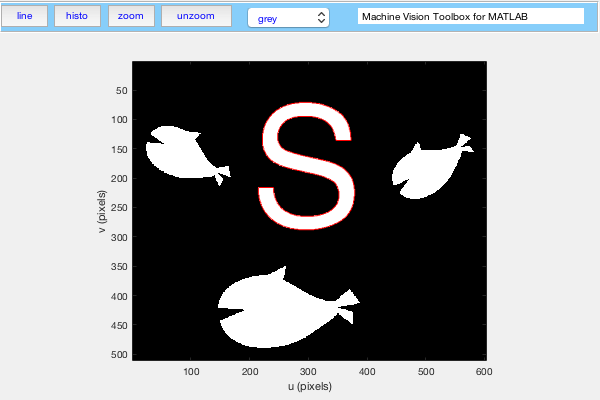



idisp(sharks) % DIFF
fv(1).plot_boundary('r')

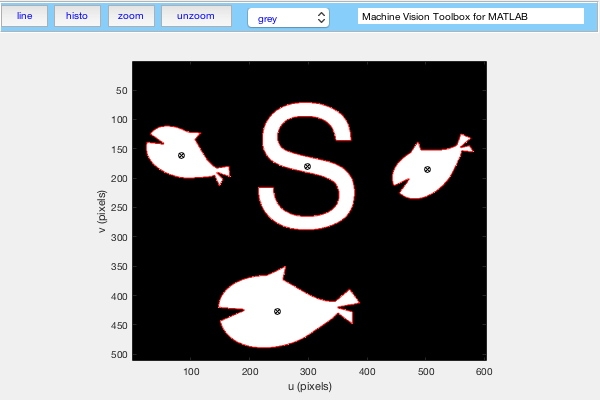


idisp(sharks) % DIFF
fv.plot_boundary('r')
fv.plot_centroid()

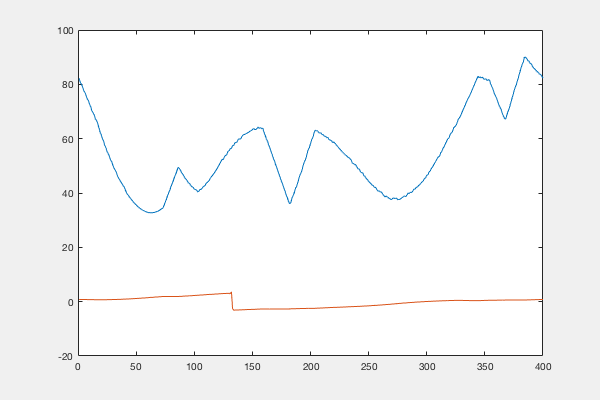


%
[r,th] = fv(2).boundary();
clf
plot([r th])

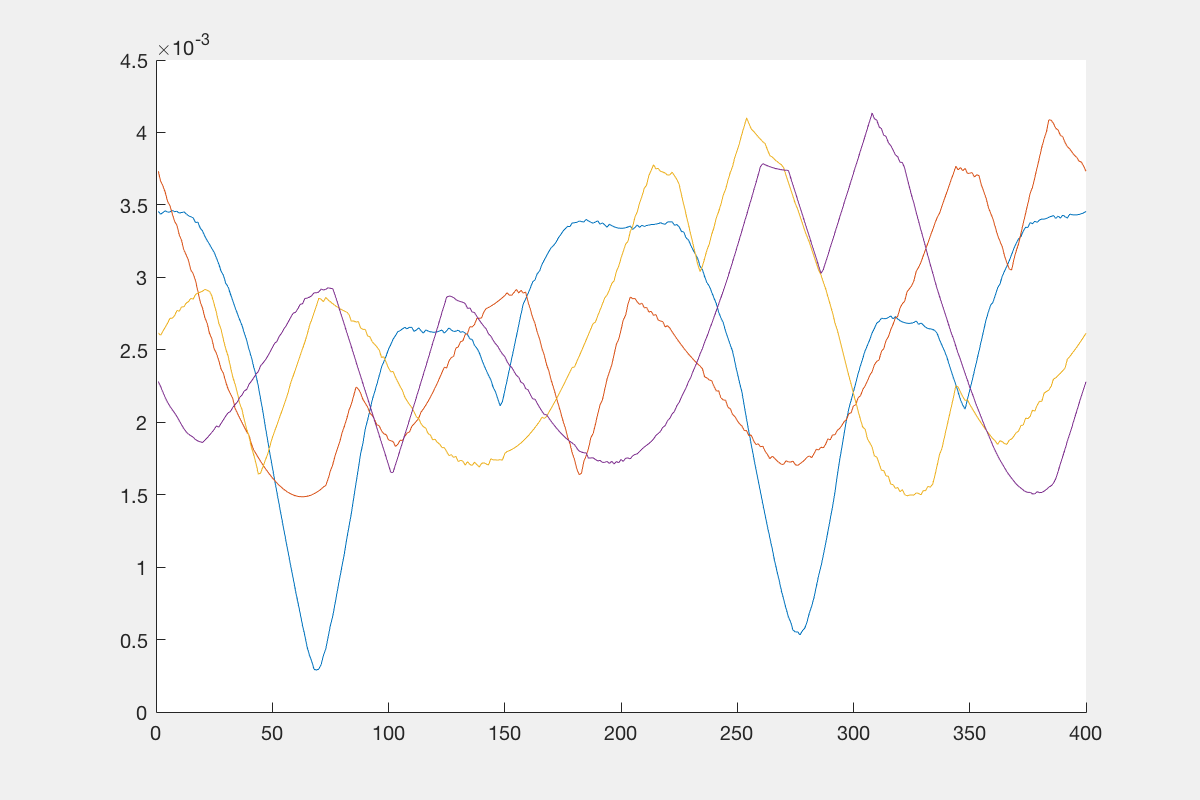


clf % DIFF
hold on
for f=fv
    [r,t] = f.boundary();
    plot(r/sum(r));
end


b = fv.boundary;

RegionFeature.boundmatch(b(:,2), b)

ans =     0.6494    1.0000    0.9854    0.9927

## 13.1.3.6  Character recognition

This requires that you have the Computer Vision System Toolbox installed

castle = iread('castle.png');
words = ocr(castle, [420 300 580 420]);

words.Text

ans = Tourist
information

Castle




words.WordConfidences'

ans =     0.8868    0.7884    0.8588

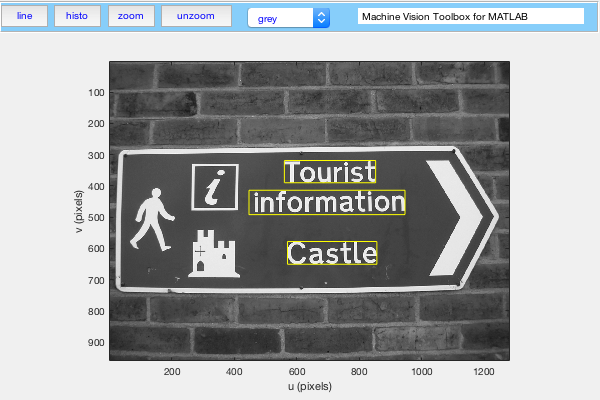


idisp(castle); %DIFF
plot_box('matlab', words.WordBoundingBoxes, 'y')

## 13.2  Line features

im = iread('5points.png', 'double');

im = testpattern('squares', 256, 256, 128);
im = irotate(im, -0.3);

edges = icanny(im);

h = Hough(edges)

h = 
Hough: nd=401, ntheta=400, interp=3x3, distance=1


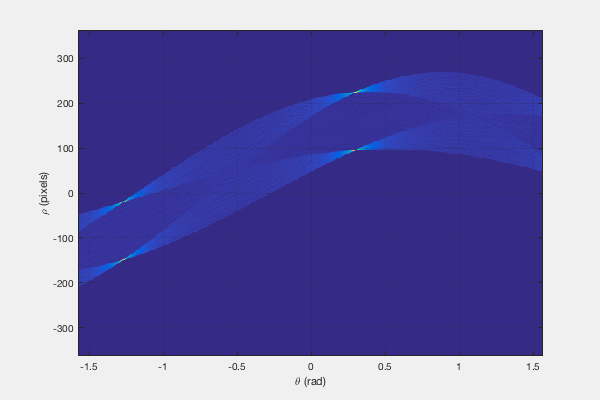


h.show();


lines = h.lines()

lines = 
theta=0.298527, rho=224.412, strength=1        
theta=0.306267, rho=96.2507, strength=0.962963 
theta=-1.27224, rho=-20.1637, strength=0.874074
theta=-1.28026, rho=-150.256, strength=0.837037
theta=0.282667, rho=94.1344, strength=0.785185 
theta=-1.25683, rho=-146.799, strength=0.77037 
theta=0.318101, rho=226.064, strength=0.718519 
theta=0.278998, rho=222.699, strength=0.703704 
theta=-1.25286, rho=-17.337, strength=0.666667 
theta=0.325784, rho=97.7635, strength=0.562963 
theta=-1.29514, rho=-23.7157, strength=0.503704



h = Hough(edges, 'suppress', 5)

h = 
Hough: nd=401, ntheta=400, interp=3x3, distance=5



lines = h.lines()

lines = 
theta=0.298527, rho=224.412, strength=1        
theta=0.306267, rho=96.2507, strength=0.962963 
theta=-1.27224, rho=-20.1637, strength=0.874074
theta=-1.28026, rho=-150.256, strength=0.837037


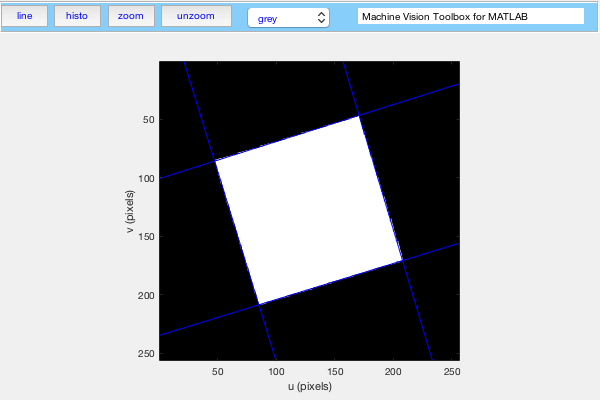


idisp(im);
h.plot('b')


im = iread('church.png', 'grey', 'double');
edges = icanny(im);
h = Hough(edges, 'suppress', 10);
lines = h.lines();

idisp(im, 'dark');
lines(1:10).plot('g');

lines = lines.seglength(edges);

lines(1)

ans = 
theta=0.0237776, rho=791.008, strength=1, length=24


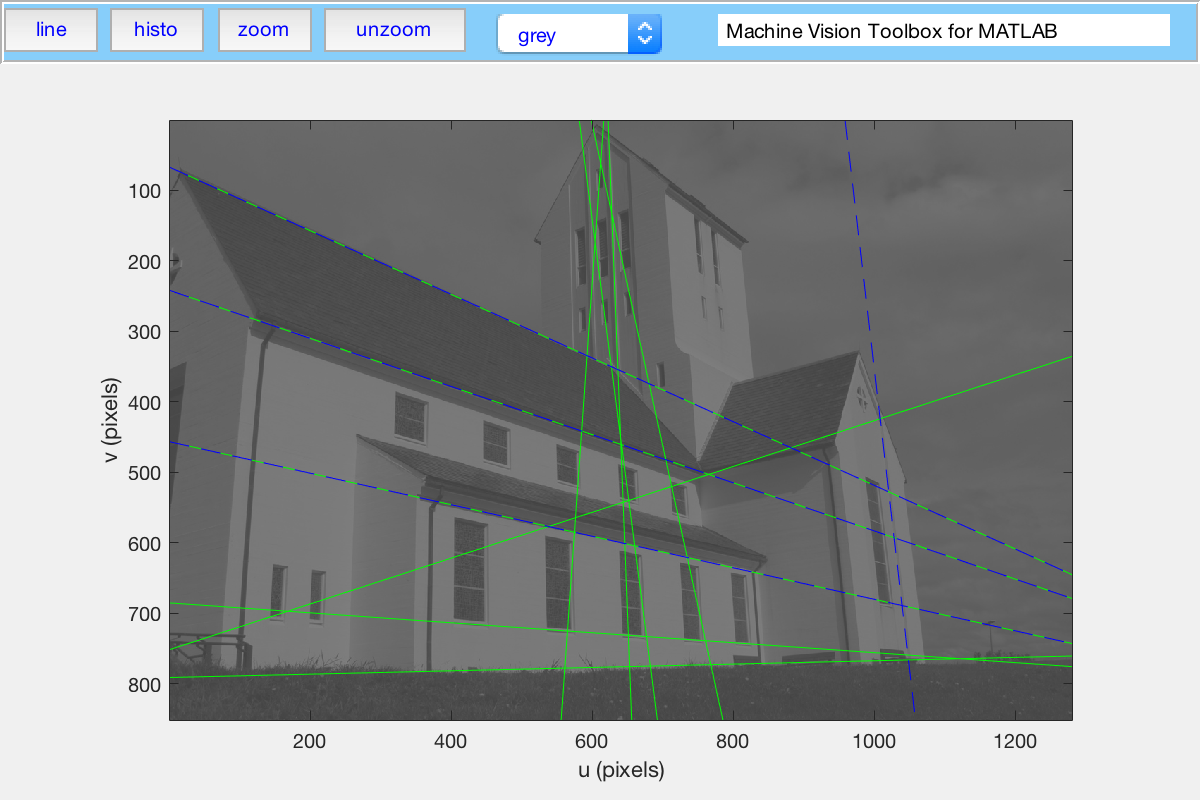


k = find( lines.length > 80);

lines(k).plot('b--')

## 13.3 Point features

## 13.3.1  Classical corner detectors

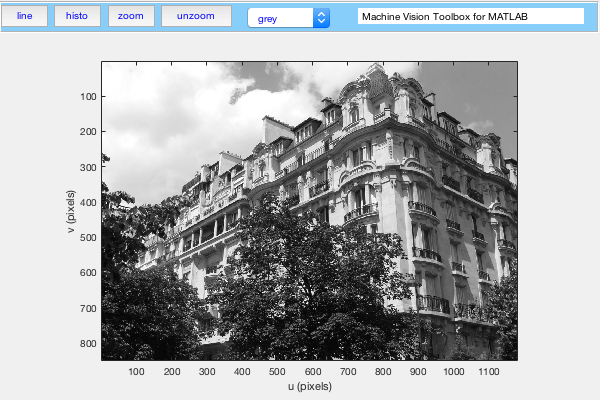

b1 = iread('building2-1.png', 'grey', 'double');
idisp(b1)


C = icorner(b1, 'nfeat', 200);

7497 corners found (0.7%),  200 corner features saved



idisp(b1, 'dark');
C.plot('ws');

Cs = icorner(b1, 'nfeat', 200, 'suppress', 10);

7497 corners found (0.7%),  200 corner features saved



length(C)

ans = 200


C(1:4)

 
ans = 
 
  (3,3), strength=2.97253e-05, descrip=(0.00704357 0.00703274 0.00344741)        
  (600,662), strength=2.13105e-05, descrip=(0.00568787   0.00448007 -0.000189851)
  (24,277), strength=1.5516e-05, descrip=(0.00577341  0.00361102 -0.00134506)    
  (54,407), strength=1.53644e-05, descrip=(0.0062428 0.00301444 0.00016217)      



C(1:5).strength

ans =    1.0e-04 *
    0.2973    0.2131    0.1552    0.1536    0.1496

C(1).u

ans = 3

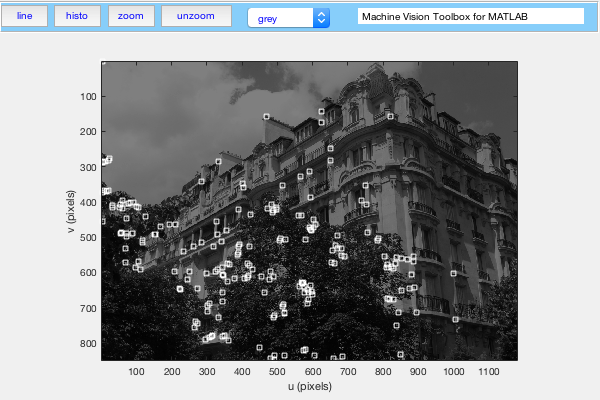


C(1:5:100).plot()


[C,strength] = icorner(b1, 'nfeat', 200);

7497 corners found (0.7%),  200 corner features saved


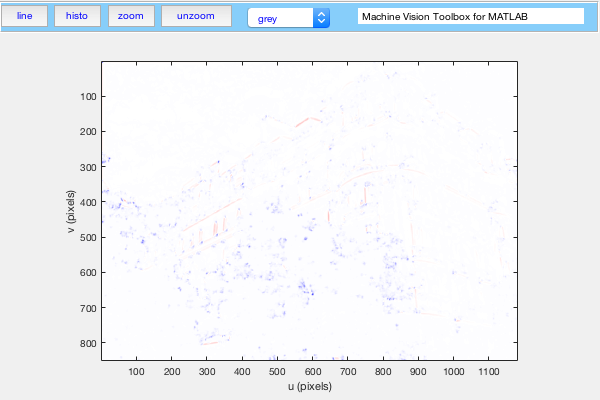


idisp(strength, 'invsigned')


b2 = iread('building2-2.png', 'grey', 'double');

C2 = icorner(b2,  'nfeat', 200);

7712 corners found (0.8%),  200 corner features saved


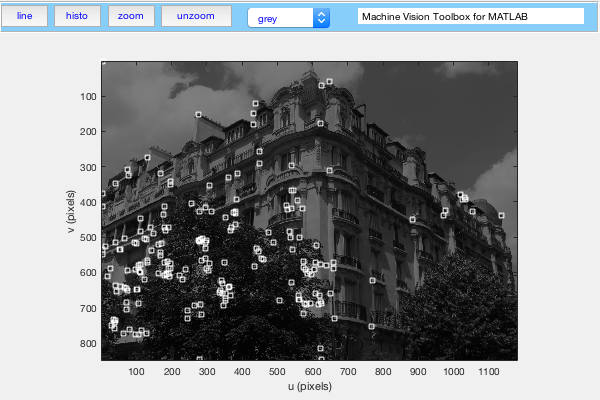

idisp(b2,'dark')
C2.plot('ws');

## 13.3.2  Scale-space corner detectors

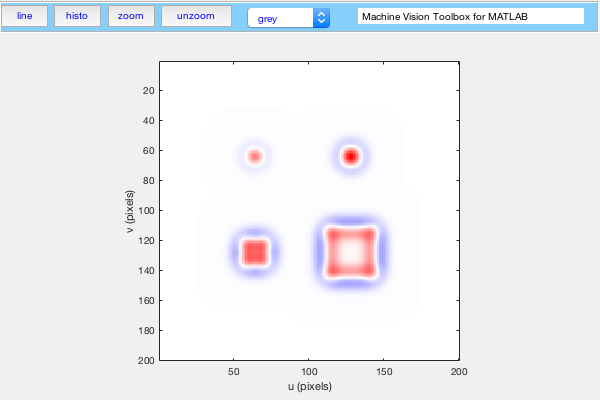

im = iread('scale-space.png', 'double');

[G,L,s] = iscalespace(im, 60, 2);

idisp(L(:,:,5), 'invsigned')


s(5)

ans = 4.0311


f = iscalemax(L, s)

 
f = 
 
  (64,64), scale=2.91548, strength=1.96449  
  (128,64), scale=4.06202, strength=1.72512 
  (128,128), scale=18.1246, strength=1.54391
  (64,128), scale=8.97218, strength=1.54057 
  (96,128), scale=15.5081, strength=0.345028
  (97,128), scale=14.7139, strength=0.34459 


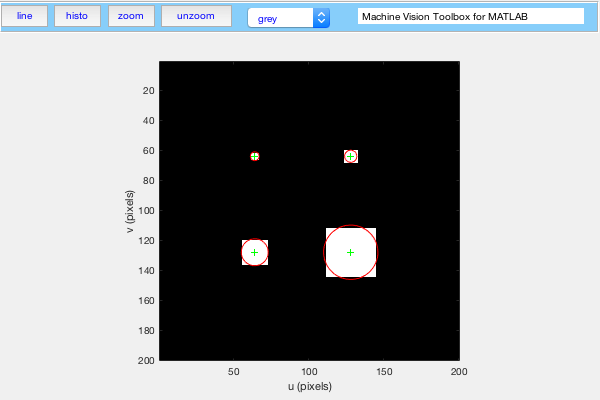


idisp(im)
f(1:4).plot('g+')

f(1:4).plot_scale('r')

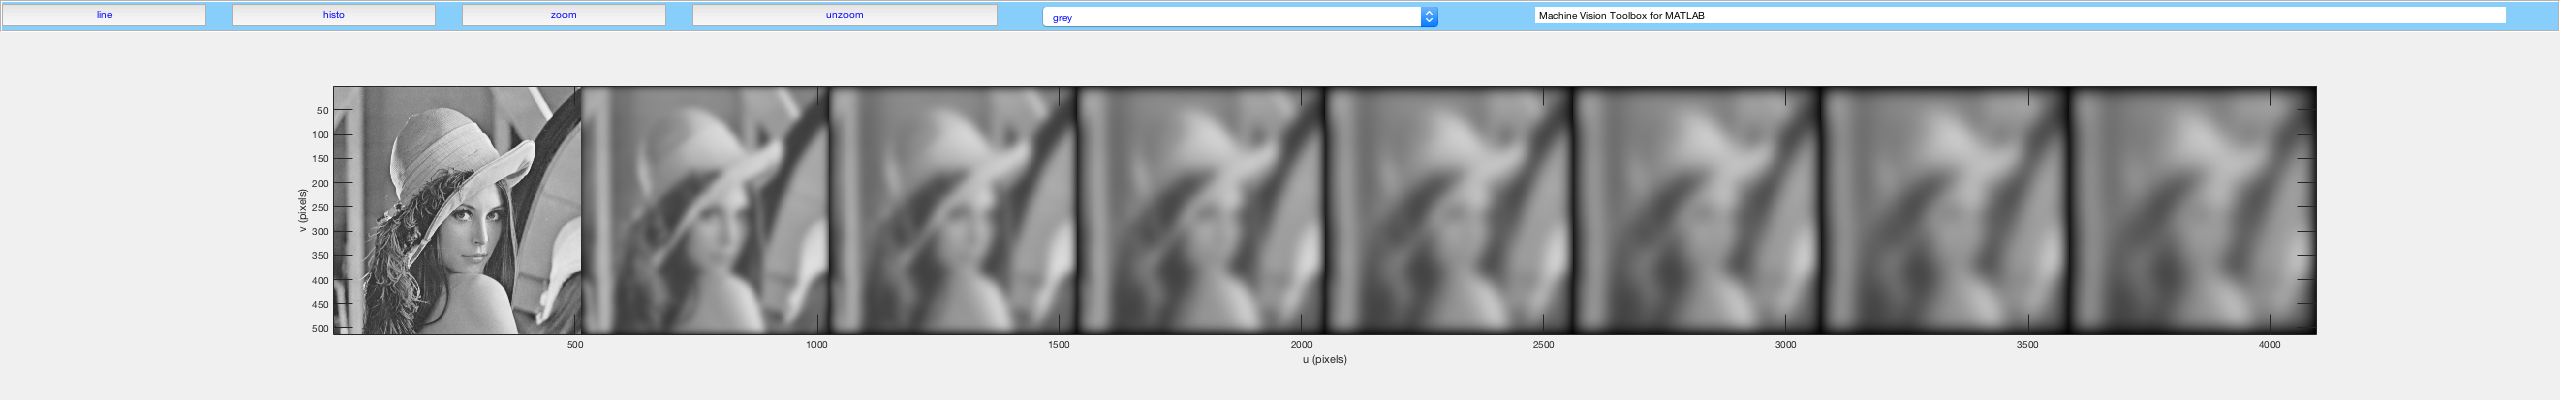


%
im = iread('lena.pgm', 'double');

[G,L] = iscalespace(im, 8, 8);

idisp(G,  'flatten', 'wide', 'square');

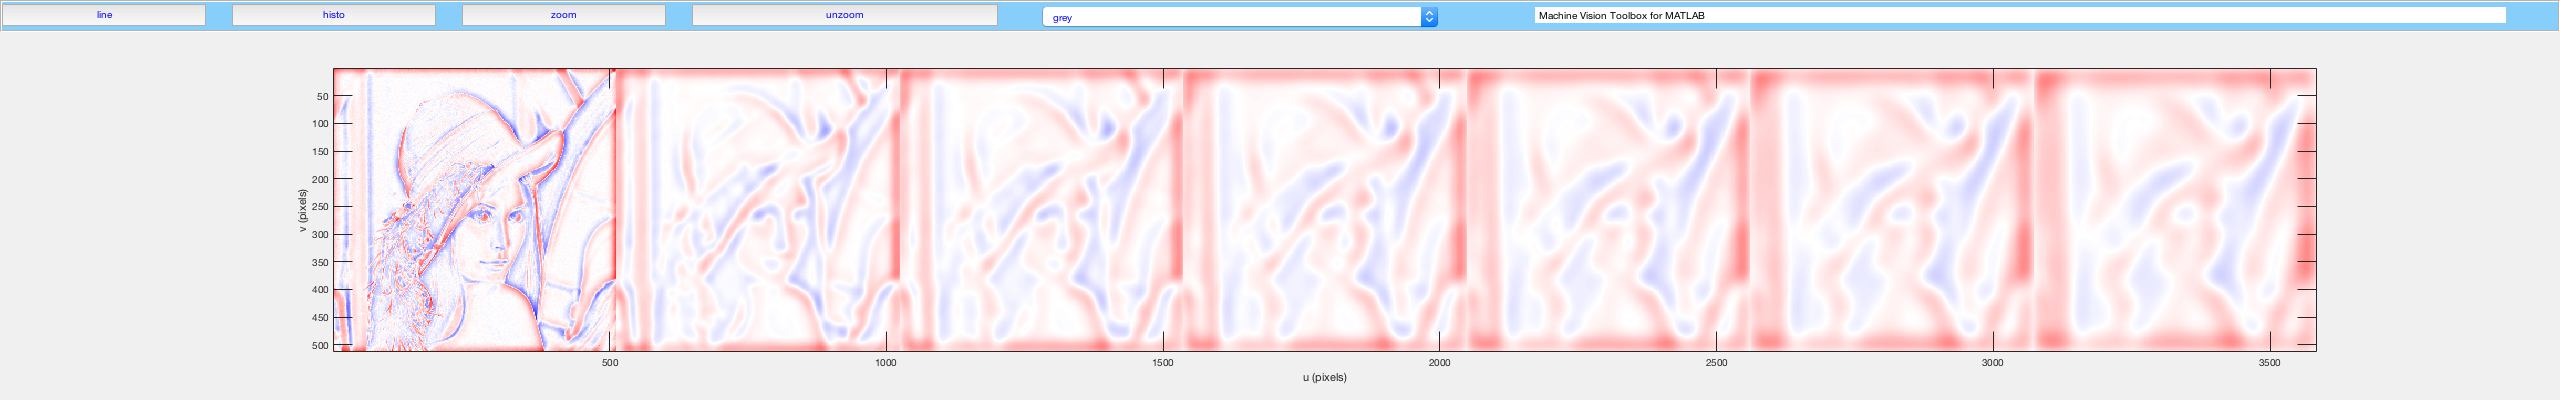

idisp(L,  'flatten', 'wide', 'square', 'invsigned');

## 13.3.2.1  Scale-space point feature

delete(gcf)

sf1 = isurf(b1, 'nfeat', 200)

2667 corners found (0.3%),  200 corner features saved
 
sf1 = 
 
200 features (listing suppressed)
  Properties: theta scale u v strength descriptor image_id



sf1(1)

 
ans = 
 
  (117.587,511.978), theta=0.453513, scale=2.16257, strength=0.0244179, descrip= ..


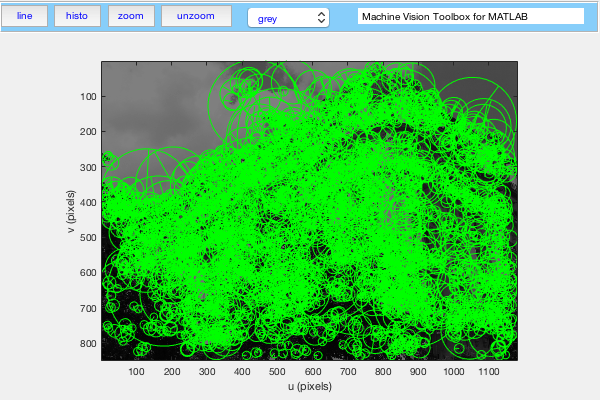


idisp(b1, 'dark');
sf1.plot_scale('g', 'clock')

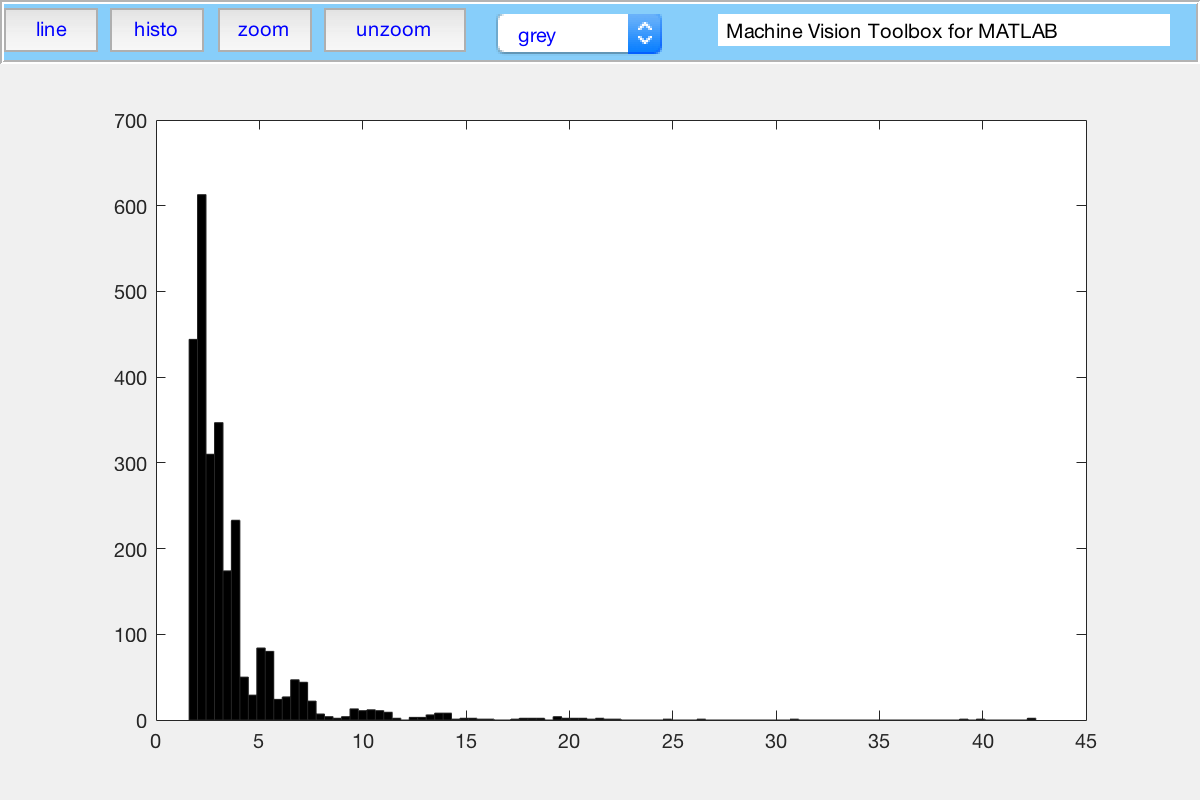


hist(sf1.scale, 100);